Lab 2 Jeff Jiang 

Problem 1

A) Show how the probability distribution of the background changes as you integrate (sum) for more days.

As the sum of the day increase, the pdf distribution of the background become more symmetric. The mean of the pdf distribution shift to the right. The hight of pdf distribution decreases because the distribution spreads out more as day increase.

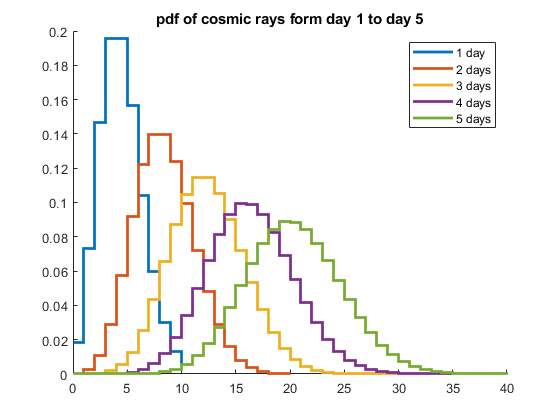

clear all;close all;clc;
cosmic = 4;
gamma = 6;

x1 = 0:10;
p1 = poisspdf(x1,cosmic);
o1 = p1;
figure
hold on
stairs(x1,p1,"LineWidth",2);
title('pdf of cosmic rays form day 1 to day 5');
xlim([0 40])
for i = 1:4
    p2 = conv(o1,p1);
    x2 = 0:10*(i+1);
    stairs(x2,p2,"LineWidth",2);
    o1 = p2;
end
legend('1 day','2 days','3 days','4 days','5 days')
hold off

B) Show that after 5 days, the summed probability distribution is still a Poisson distribution. Explain why this makes sense from a mathematical and conceptual point of view.

After 5 days and the summed probability distribution is similar with poisson pdf of 5 times the cosimc as show below. 

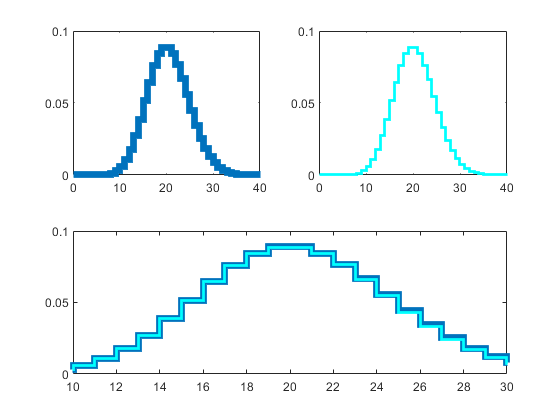

p3 = poisspdf(x2,cosmic*5);
figure
subplot(2,2,1);

stairs(x2,p3,"LineWidth",5);
xlim([0 40]);
subplot(2,2,2);
stairs(x2,p2,"LineWidth",2,"Color",'cyan');
xlim([0 40]);
subplot(2,2,[3,4]);
stairs(x2,p3,"LineWidth",5);
hold on
stairs(x2,p2,"LineWidth",2,"Color",'cyan');
xlim([10 30]);
hold off

C) Show how the probability distribution evolves as you *average* days. Calculate for many different ranges of days, and explore the shape of the distribution as the number of days becomes larger. Discuss this in relation to both B) and the central limit theoem.

As the days increase and take the average of the x-axes the distribution becomes narrower. The mean stady the same.

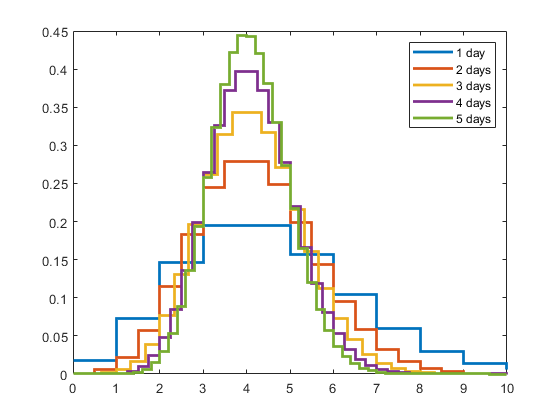

figure
o2=p1;
nx1 = x1 / 1;
np1 = p1 * 1;
stairs(nx1,np1,"LineWidth",2);
hold on
for i = 1:4
    p3 = conv(o2,p1);
    x3 = 0:10*(i+1);
    nx2 = x3 / (i+1);
    np2 = p3 * (i+1);
    stairs(nx2,np2,"LineWidth",2);
    o2 = p3;
end
legend('1 day','2 days','3 days','4 days','5 days')
hold off

D) Pick some number of days N, and assume you saw Y*N gamma rays from your source. Calculate the 'sigma' of your observation. [In reality the number of gamma-rays seen from a source will also fluctuate, but we're going to ignore that complication for a couple of labs.]

I picked day 1 for this part. 

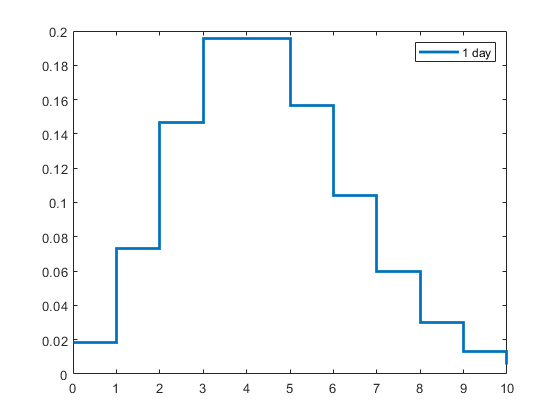

stairs(x1,p1,"LineWidth",2)
legend('1 day')

pd1 = makedist("Poisson","lambda",cosmic);
probability3 = cdf(pd1,gamma);
disp("The probability to find 6 gamma is "+ probability3);

The probability to find 6 gamma is 0.88933


sigma4 = norminv(probability3);
disp("The sigma for the probability is "+ sigma4);

The sigma for the probability is 1.223


Problem 2

A) Show how the distribution changes as you average over more observing intervals.

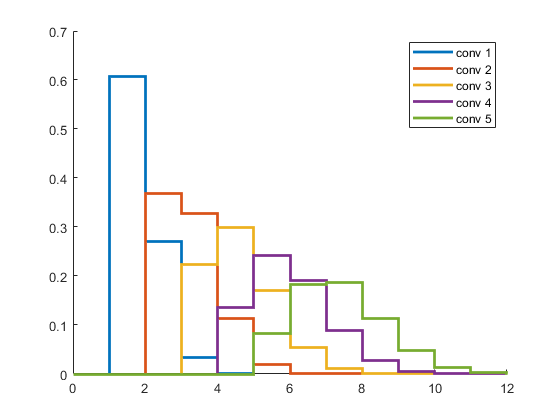

Rx1 = 0:5;
Rp1 = raylpdf(Rx1,1);
Ro1 = Rp1;
figure
hold on
stairs(Rx1,Rp1,"LineWidth",2);
for i = 2:5
    Rp2 = conv(Ro1,Rp1);
    Rx2 = 0:5*i;
    stairs(Rx2,Rp2,"LineWidth",2);
    Ro1 = Rp2;
end
xlim([0 12])
legend('conv 1','conv 2','conv 3','conv 4','conv 5')
hold off

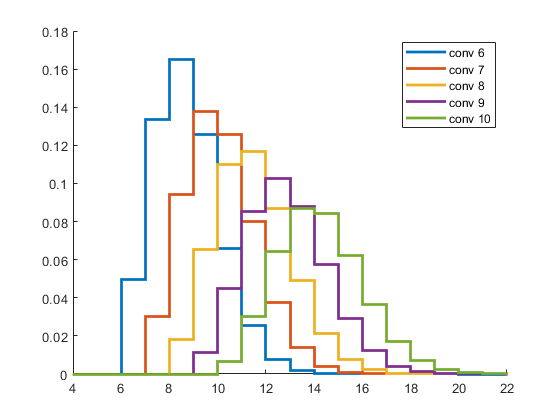


figure
hold on
for i = 6:10
    Rp2 = conv(Ro1,Rp1);
    Rx2 = 0:5*i;
    stairs(Rx2,Rp2,"LineWidth",2);
    Ro1 = Rp2;
end
xlim([4 22])
legend('conv 6','conv 7','conv 8','conv 9','conv 10')
hold off

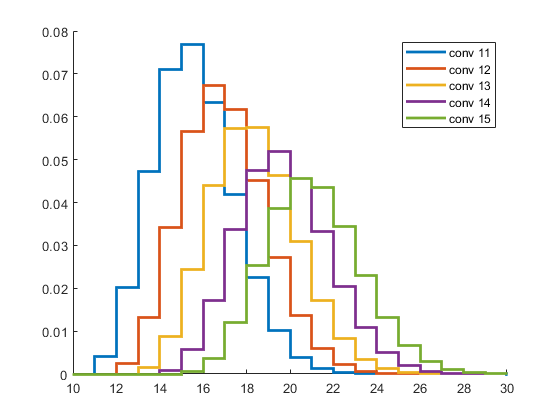


figure
hold on
for i = 11:15
    Rp2 = conv(Ro1,Rp1);
    Rx2 = 0:5*i;
    stairs(Rx2,Rp2,"LineWidth",2);
    Ro1 = Rp2;
end
xlim([10 30])
legend('conv 11','conv 12','conv 13','conv 14','conv 15')
hold off

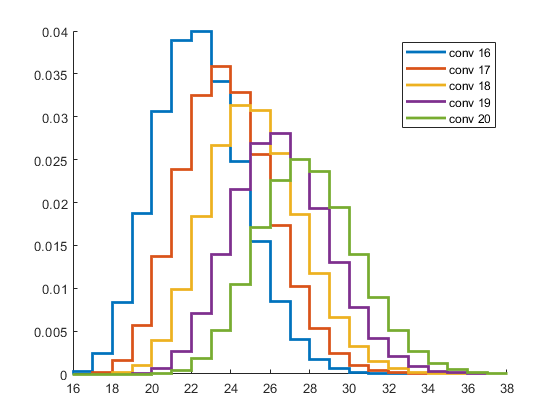


figure
hold on
for i = 16:20
    Rp2 = conv(Ro1,Rp1);
    Rx2 = 0:5*i;
    stairs(Rx2,Rp2,"LineWidth",2);
    Ro1 = Rp2;
end
xlim([16 38])
legend('conv 16','conv 17','conv 18','conv 19','conv 20')
hold off

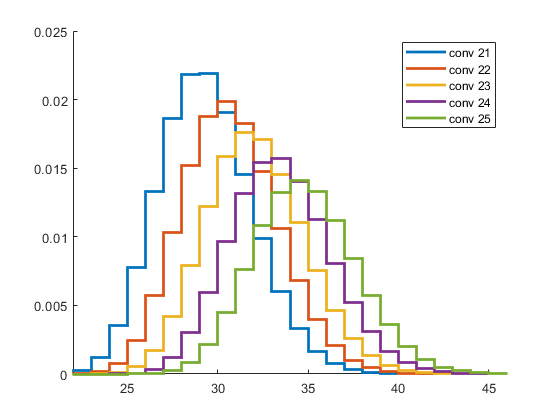


figure
hold on
for i = 21:25
    Rp2 = conv(Ro1,Rp1);
    Rx2 = 0:5*i;
    stairs(Rx2,Rp2,"LineWidth",2);
    Ro1 = Rp2;
end
xlim([22 46])
legend('conv 21','conv 22','conv 23','conv 24','conv 25')
hold off

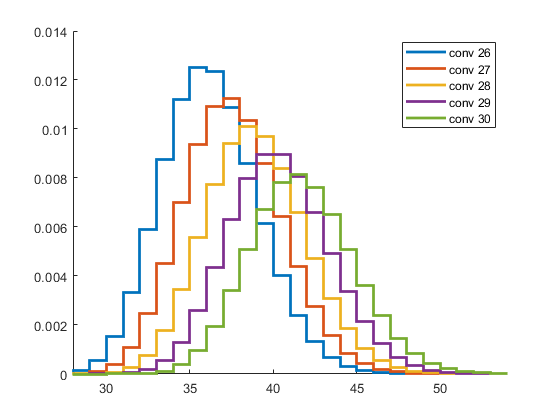


figure
hold on
for i = 26:30
    Rp2 = conv(Ro1,Rp1);
    Rx2 = 0:5*i;
    stairs(Rx2,Rp2,"LineWidth",2);
    Ro1 = Rp2;
end
xlim([28 54])
legend('conv 26','conv 27','conv 28','conv 29','conv 30')
hold off

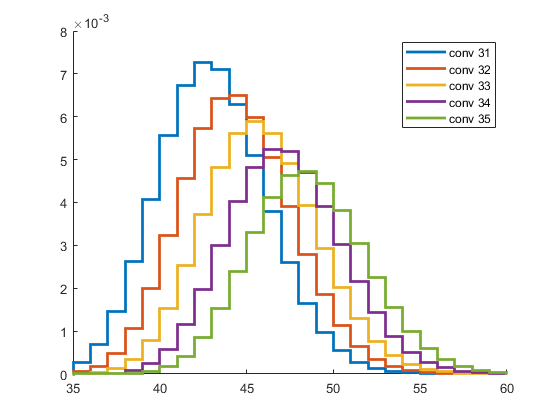


figure
hold on
for i = 31:35
    Rp2 = conv(Ro1,Rp1);
    Rx2 = 0:5*i;
    stairs(Rx2,Rp2,"LineWidth",2);
    Ro1 = Rp2;
end
xlim([35 60])
legend('conv 31','conv 32','conv 33','conv 34','conv 35')
hold off

B) Discuss how the shape changes. Does it approach a Gaussian distribution? If yes, after how many intervals?

The shape become less skewed as more convolution are done. It does approach a Gaussian distribution around 25th convolution. 

Problem 3

A) From looking at all the other pixels in your image, you can measure the width of the background Gaussian distribution X (pick something). Assuming you see a signal of strength Y (pick a floating-point number; optical CCDs are not sensitive enough to count photons so the readings are floating point brightnesses, not integer photons). Calculate the significance of your detection. Can you claim a discovery (traditionally 5-sigma or more)?

The Gaussian distribution I piked is Normal distribution with Mean (mu) 3 and Standard deviation (sigma) 1. The floating-point number I picked is 9.5.

The result I got for sigma is 6.5 which mean I can claim a discovery since is 5 sigma or more.

p3pd1 = normcdf(9.5,3,1,'upper');

p3pd1 = 4.0160e-11

disp("The probability to find 6.5 at normal distribution is "+ p3pd1);

The probability to find 0.5 at normal distribution is 4.016e-11


p3sigma1 = norminv(p3pd1);
disp("The sigma for the probability is "+ p3sigma1);

The sigma for the probability is -6.5


B) If you have to look for a signal in 10k pixels, what is the probability distribution of your background? (*Clearly* state the statistical question, then turn that into math using your background distribution from part 1 of this problem.)

Statistical Question: The background is a Gaussian Distribution, with a mean of 3. The stronger the signal the more events we expect. So what is the probablilty of the background produsing a signal with greater than 9.5 events with signal in 10k pixels? 

p3pd2 = 10000*p3pd1;

p3pd2 = 4.0160e-07

disp("The probability to find 6.5 at normal distribution is "+ p3pd2);

C) Taking your brightest candidate signal from the region (assume it has the same signal as in part 1), calculate the significance of your detection.

p3sigma2 = norminv(p3pd2);
disp("The sigma for the probability is "+ p3sigma2);

The sigma for the probability is -4.9346


Problem 4

A) Calculate the signal required for a 5-sigma detection in Version 1

p4x1 = makedist("Normal","mu",3,"sigma",1);
p4sigma1 = normcdf(5,'upper')

p4sigma1 = 2.8665e-07

p4signal1 = icdf(p4x1,1-p4sigma1)

det1 = 8.0000

B) Calculate the signal required for a 5-sigma detection in Version 2

p4signal2 = icdf(p4x1,1-p4sigma1/10000)

p4signal2 = 9.5505

C) Discuss how much brighter the signal must be for discoverey if you have a trials factor of 10k. Looking at your probability distributions, explain why the sensitivity penalty due to a trials factor is so low.

I think since this is a guassian distribution, the senstive pentaly due to a lot of trails is low, because the symmetry of the distribution. When you have more trials the probability falls off more quickly. 

D) If you changed the trials factor significantly (orders of magnitude), how large is the effect on your 5-sigma sensitivity threshold?

In a gaussian distribution if you change the trials factor significanly, the effect on you 5-sigma sensitivity threshold should change less and less significant. 